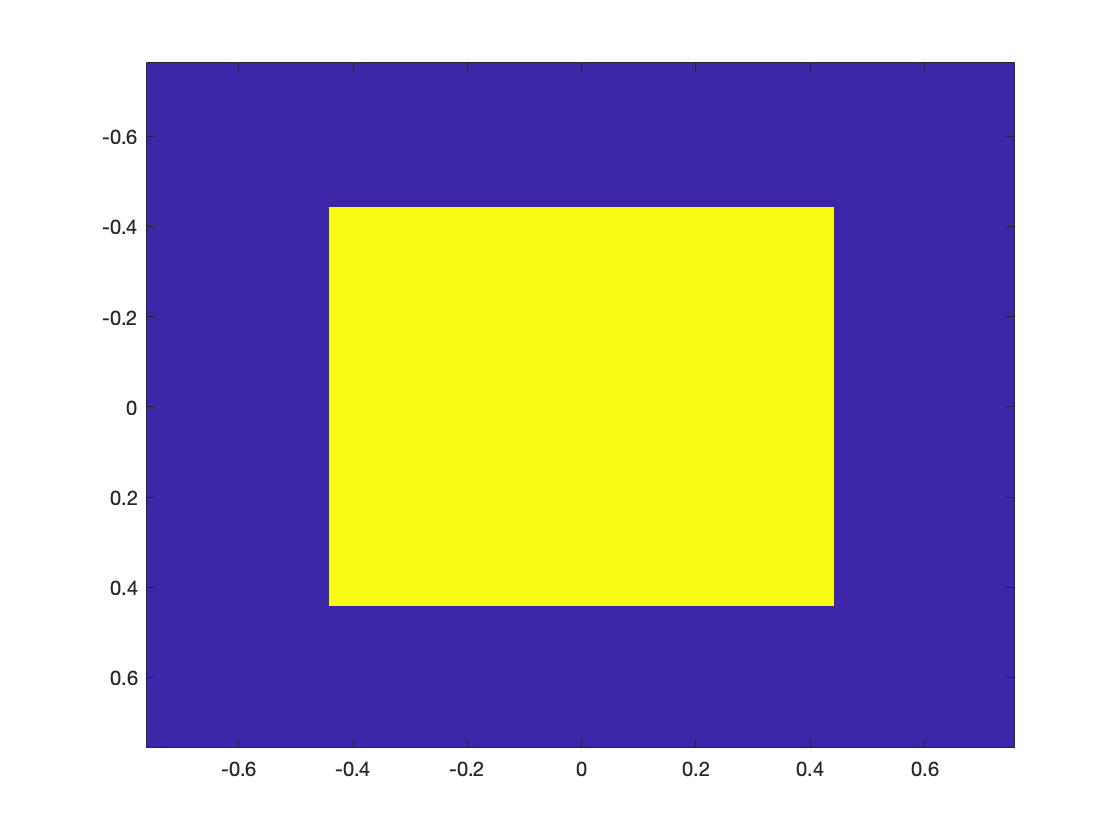

%% Set data 
N = 257; % x,y sampling points
lambda = 633; % wavelength
k = 2*pi/lambda;
z = [0 2 1]*lambda; % propargate distance
z = reshape(repmat(z,256*256,1),256,256,[]);
Endpoint = 1.2E-3*lambda; % size/2

%% Create field at starting point (z=0)
x = linspace(-Endpoint,Endpoint,N); 
x = x(1:end-1); 
dx = x(2)-x(1);
xi = linspace(-dx/2,dx/2,N); 
xi = xi(1:end-1); 

y = linspace(-Endpoint,Endpoint,N);
y = y(1:end-1);
dy = y(2)-y(1);
eta = linspace(-dy/2,dy/2,N);
eta = eta(1:end-1);

[X,Y] = meshgrid(x,y);
[Xi,Eta] = meshgrid(xi,eta);

w = 0.7E-3*lambda;
ur_o=(X>-w&X<w)&(Y>-w&Y<w);

ur_o = fftshift(ur_o);
Ur_o = fft2(ur_o);
Ur_o = ifftshift(Ur_o); 

%% Calculate propagation in Fourier space
% Uph = exp(2*pi*z*sqrt(lambda^-2-(xi^2+eta^2))
% f(x)=1forx>-0.5&x<0.5
Uph = exp(2*pi*1i*sqrt((lambda^-2)-(Xi.^2+Eta.^2)).*z);
U=Ur_o.*Uph;

%% Propagation from  1 -> 2
% index = 3 of 3rd dimention
U(:,:,3) = U(:,:,3) .* Uph(:,:,3);

%% IFT
U = fftshift(U);
u = ifft2(U);
u = ifftshift(u); % shift back for comparison

% Results
imagesc(x,y,real(u(:,:,1)))

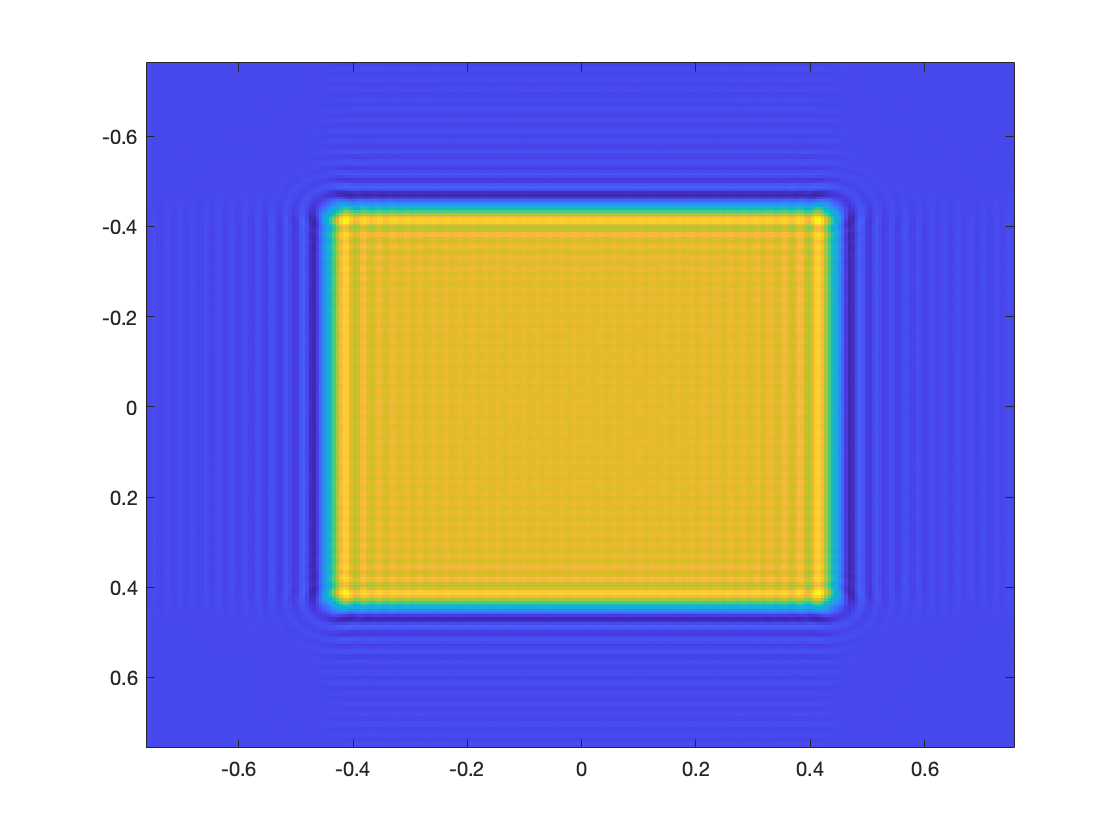


imagesc(x,y,real(u(:,:,2)))


imagesc(x,y,real(u(:,:,3)))